

Nterms=35 %Just testing around, this is accurate within ~15 decimals.  

Nterms = 35

testX=0.1 % Between 0 and 0.3927

testX = 0.1000

testY=0.2 % Between 0 and 0.1963 This will blow up if out of this range.

testY = 0.2000

xSteps=50

xSteps = 50

ySteps=25

ySteps = 25

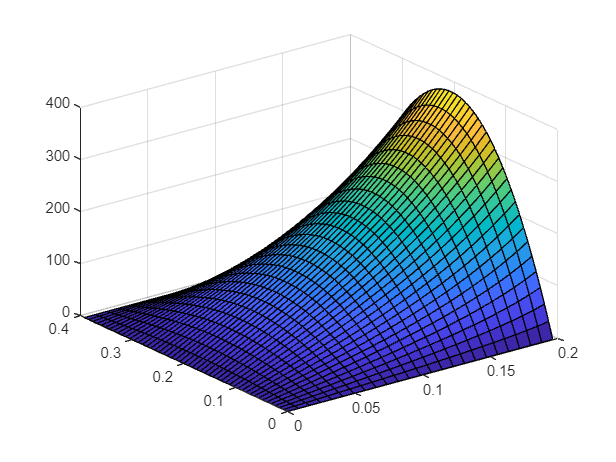


xTerms=linspace(0,pi/8,xSteps);
yTerms=linspace(0,pi/16,ySteps);
zTerms = zeros(xSteps, ySteps);
for i = 1:xSteps
    for j = 1:ySteps
        zTerms(i,j) = Analyticalsum(xTerms(i), yTerms(j), Nterms);
    end
end

figure
surf(yTerms, xTerms, zTerms)

function hi = Analyticalsum(x,y,Nterms)
    hi = 0;

Analytical= @(x,y,n) (625*(4*sin(pi*n/2)^2-pi*n*sin(pi*n))/(2*n^3*pi*sinh(pi*n/2)))...
    *sin(8*n*x)*sinh(8*n*y);
    for i = 1:Nterms
        hi = hi + Analytical(x,y,i);
    end
end